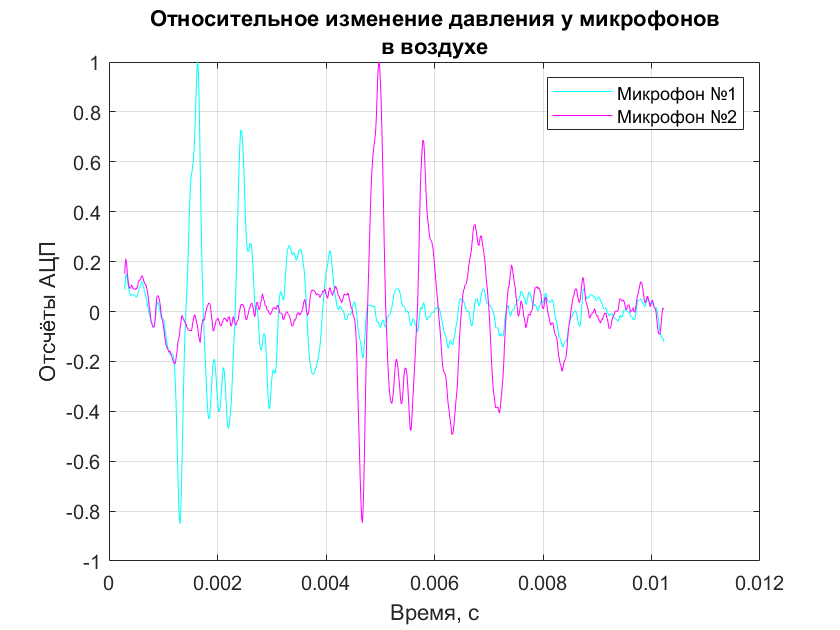

close all;
clear variables;
AV = fscanf(fopen('Desktop/Study/MIPT/5. GET/6. Labs/Lab 3. Звук и его скорость в среде/Lab-3/air.txt', 'r'), '%f', [2 Inf]);
BV = fscanf(fopen('Desktop/Study/MIPT/5. GET/6. Labs/Lab 3. Звук и его скорость в среде/Lab-3/breath.txt', 'r'), '%f', [2 Inf]);
t = fscanf(fopen('Desktop/Study/MIPT/5. GET/6. Labs/Lab 3. Звук и его скорость в среде/Lab-3/totalTime.txt', 'r'), '%f');
Temp = fscanf(fopen('Desktop/Study/MIPT/5. GET/6. Labs/Lab 3. Звук и его скорость в среде/Lab-3/temperature.txt', 'r'), '%f');
SF = fscanf(fopen('Desktop/Study/MIPT/5. GET/6. Labs/Lab 3. Звук и его скорость в среде/Lab-3/samplingFrequency.txt', 'r'), '%f');
WF = fscanf(fopen('Desktop/Study/MIPT/5. GET/6. Labs/Lab 3. Звук и его скорость в среде/Lab-3/volumeFractionWater.txt', 'r'), '%f');
fclose('all');
tv = (0:(1/SF):t)';
l = 1.158;
windowSize = 5;
b = (1/windowSize)*ones(1, windowSize);
a = 1;
aF1 = filter(b, a, AV(1, :));
aF2 = filter(b, a, AV(2, :));
bF1 = filter(b, a, BV(1, :));
bF2 = filter(b, a, BV(2, :));
start = 30;
aF1 = aF1(:, start:end);
aF2 = aF2(:, start:end);
bF1 = bF1(:, start:end);
bF2 = bF2(:, start:end);
t = tv(start:end)';
callibrA1 = polyfit(t, aF1, 3);
callibrA2 = polyfit(t, aF2, 3);
callibrB1 = polyfit(t, bF1, 3);
callibrB2 = polyfit(t, bF2, 3);
a1 = aF1 - polyval(callibrA1, t);
aN1 = a1./max(a1);
a2 = aF2 - polyval(callibrA2, t);
aN2 = a2./max(a2);
b1 = bF1 - polyval(callibrB1, t);
bN1 = b1./max(b1);
b2 = bF2 - polyval(callibrB2, t);
bN2 = b2./ max(b2);
f1 = figure();
plot(t, aN1, 'c');
hold on;
plot(t, aN2, 'm');
hold off;
grid on;
title({'Относительное изменение давления у микрофонов', 'в воздухе'});
ylabel('Отсчёты АЦП');
xlabel('Время, с');
legend('Микрофон №1', 'Микрофон №2');
saveas(f1, "air.png")

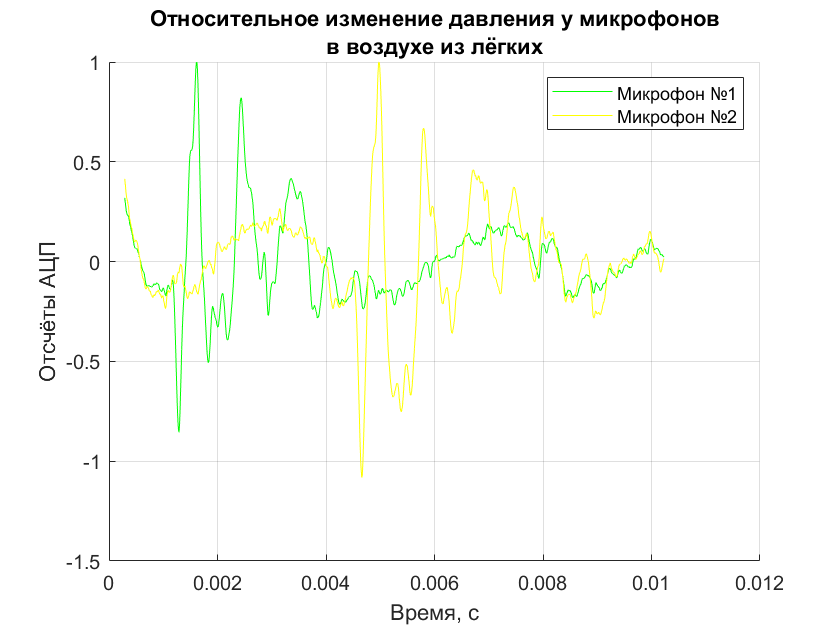

f2 = figure();
hold on;
plot(t, bN1, 'g');
plot(t, bN2,'y');
hold off;
grid on;
title({'Относительное изменение давления у микрофонов', 'в воздухе из лёгких'});
ylabel('Отсчёты АЦП');
xlabel('Время, с');
legend('Микрофон №1', 'Микрофон №2')
saveas(f2, "breath.png");

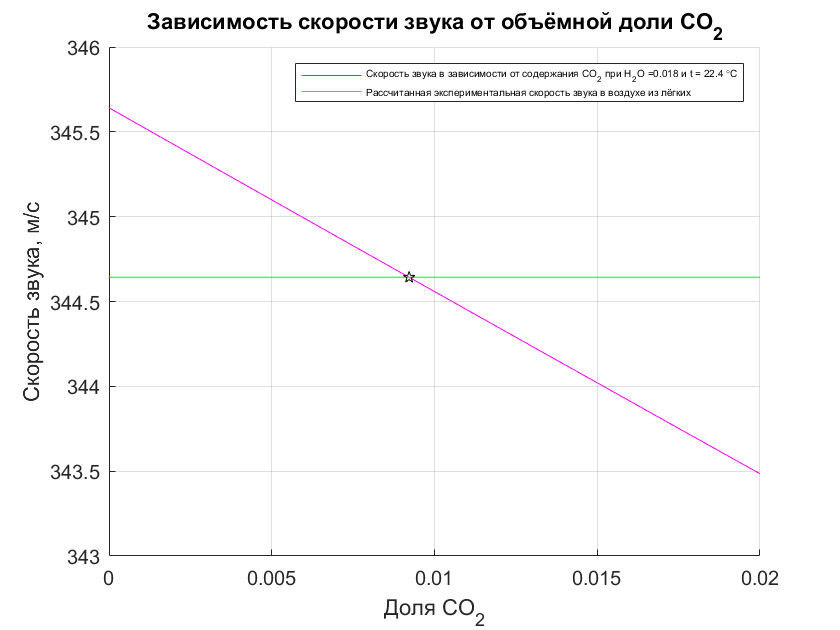

tA1 = t(aN1 == 1);
tA2 = t(aN2 == 1);
da = tA2 - tA1;
Va = l/da;
tB1 = t(bN1 == 1);
tB2 = t(bN2 == 1);
db = tB2 - tB1;
Vb = l/db;
R = 8.314;
Ma = 28.97;
MH2O = 18.01;
MCO2 = 44.01;
CpA = 1.0036;
CpH2O = 1.863;
CpCO2 = 0.838;
CvA = 0.7166;
CvH2O = 1.403;
CvCO2 = 0.649;
frCO2 = 0:0.00001:0.02;
p = Vb*ones(1, length(frCO2));
M = (1-WF-frCO2)*Ma + WF*MH2O + frCO2*MCO2;
Cp = CpA*(1-WF-frCO2)*Ma+CpH2O*WF*MH2O+CpCO2*frCO2*MCO2;
Cv = CvA*(1-WF-frCO2)*Ma+CvH2O*WF*MH2O+CvCO2*frCO2*MCO2;
g = Cp./Cv;
p1 = sqrt(1000*g*R*(Temp+273.15)./M);
n = frCO2(p1 <= Vb);
n = n(1);
f3 = figure();
hold on;
plot(frCO2, p1,'m');
plot(frCO2, p,'g');
plot(n, Vb, 'kp');
hold off;
grid on;
title('Зависимость скорости звука от объёмной доли CO_2');
ylabel('Скорость звука, м/с');
xlabel('Доля CO_2');
legend(['Скорость звука в зависимости от содержания CO_2 при H_2O =', num2str(WF),' и t = ', num2str(Temp), ' \circC'], 'Рассчитанная экспериментальная скорость звука в воздухе из лёгких','fontsize',5);
saveas(f3, "velocity.png");